%% Conditional DCGAN + PILAE Classification in MATLAB
clear; clc; close all;
rng(42);

%% Paths
PROJECT_ROOT = 'D:\PROJECT_ROOT';
DATASET_PATH = fullfile(PROJECT_ROOT, 'DATASET');
MODELS_PATH  = fullfile(PROJECT_ROOT, 'models');
if ~exist(MODELS_PATH, 'dir'), mkdir(MODELS_PATH); end

%% Hyperparameters
IMAGE_SIZE = 64;
BATCH_SIZE = 32;
nz         = 100;
ngf        = 64;
ndf        = 64;
nc         = 3;
EPOCHS     = 20;
LR         = 0.0002;
BETA1      = 0.5;

%% ── 1. Load Dataset ──────────────────────────────────────
imds = imageDatastore(DATASET_PATH, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

CLASS_NAMES = categories(imds.Labels);
NUM_CLASSES = numel(CLASS_NAMES);
fprintf('Classes: %s\n', strjoin(CLASS_NAMES, ', '));

Classes: Guava_Healthy, Guava_Unhealthy, Lemon, Lychee_Healthy, Lychee_Unhealthy, Mango_Unhealthy


fprintf('Number of classes: %d\n', NUM_CLASSES);

Number of classes: 6


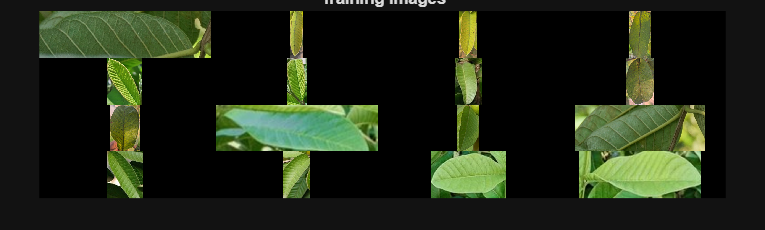


augmenter = imageDataAugmenter('RandXReflection', true);
augimds = augmentedImageDatastore([IMAGE_SIZE IMAGE_SIZE nc], imds, ...
    'DataAugmentation', augmenter, ...
    'ColorPreprocessing', 'gray2rgb');
augimds.MiniBatchSize = BATCH_SIZE;

%% Preview training images
figure;
montage(imds, 'Size', [4 4]);
title('Training Images');


%% ── 2. Build Generator ───────────────────────────────────
function lgraph = buildGenerator(nz, ngf, nc, NUM_CLASSES)
    inputDim = nz + NUM_CLASSES;
    layers = [
        imageInputLayer([1 1 inputDim], 'Name','gen_in','Normalization','none')
        transposedConv2dLayer(4, ngf*8, 'Name','tconv1','Stride',1,'Cropping','same')
        batchNormalizationLayer('Name','bn1')
        reluLayer('Name','relu1')
        transposedConv2dLayer(4, ngf*4, 'Name','tconv2','Stride',2,'Cropping','same')
        batchNormalizationLayer('Name','bn2')
        reluLayer('Name','relu2')
        transposedConv2dLayer(4, ngf*2, 'Name','tconv3','Stride',2,'Cropping','same')
        batchNormalizationLayer('Name','bn3')
        reluLayer('Name','relu3')
        transposedConv2dLayer(4, ngf,   'Name','tconv4','Stride',2,'Cropping','same')
        batchNormalizationLayer('Name','bn4')
        reluLayer('Name','relu4')
        transposedConv2dLayer(4, nc,    'Name','tconv5','Stride',2,'Cropping','same')
        tanhLayer('Name','tanh_out')
    ];
    lgraph = layerGraph(layers);
end

%% ── 3. Build Discriminator ───────────────────────────────
function lgraph = buildDiscriminator(nc, ndf, NUM_CLASSES)
    inputChannels = nc + NUM_CLASSES;
    layers = [
        imageInputLayer([64 64 inputChannels],'Name','disc_in','Normalization','none')
        convolution2dLayer(4, ndf,   'Name','conv1','Stride',2,'Padding','same')
        leakyReluLayer(0.2,'Name','lrelu1')
        convolution2dLayer(4, ndf*2, 'Name','conv2','Stride',2,'Padding','same')
        batchNormalizationLayer('Name','bn2')
        leakyReluLayer(0.2,'Name','lrelu2')
        convolution2dLayer(4, ndf*4, 'Name','conv3','Stride',2,'Padding','same')
        batchNormalizationLayer('Name','bn3')
        leakyReluLayer(0.2,'Name','lrelu3')
        convolution2dLayer(4, ndf*8, 'Name','conv4','Stride',2,'Padding','same')
        batchNormalizationLayer('Name','bn4')
        leakyReluLayer(0.2,'Name','lrelu4')
        convolution2dLayer(4, 1,     'Name','conv5','Stride',1,'Padding','same')
        globalAveragePooling2dLayer('Name','gap')
        sigmoidLayer('Name','sigmoid_out')
    ];
    lgraph = layerGraph(layers);
end

%% ── 4. Helper: Label Maps ────────────────────────────────
function labelMaps = makeConditionalMaps(labels, NUM_CLASSES, H, W)
    N = numel(labels);
    labelMaps = zeros(H, W, NUM_CLASSES, N, 'single');
    for i = 1:N
        labelMaps(:,:, labels(i), i) = 1;
    end
end

%% ── 5. Initialize Networks ───────────────────────────────
dlnetG = dlnetwork(buildGenerator(nz, ngf, nc, NUM_CLASSES));
dlnetD = dlnetwork(buildDiscriminator(nc, ndf, NUM_CLASSES));
fprintf('Networks initialized.\n');

Networks initialized.



%% ── 6. Training Step Functions ───────────────────────────
function [gradD, lossD, dlFakeImgs] = discriminatorStep(dlnetG, dlnetD, dlReal, dlNoise, labels, NUM_CLASSES)
    dlFakeImgs  = forward(dlnetG, dlNoise);
    fakeResized = dlresize(dlFakeImgs, 'OutputSize', [64 64]);

    N = size(extractdata(fakeResized), 4);
    labelMapsForFake = zeros(64, 64, NUM_CLASSES, N, 'single');
    for i = 1:N
        labelMapsForFake(:,:, labels(i), i) = 1;
    end
    dlFakeMaps  = dlarray(labelMapsForFake, 'SSCB');
    dlFakeInput = cat(3, fakeResized, dlFakeMaps);

    outReal = forward(dlnetD, dlReal);
    outFake = forward(dlnetD, dlFakeInput);

    lossReal = mean(-log(outReal + 1e-8), 'all');
    lossFake = mean(-log(1 - outFake + 1e-8), 'all');
    lossD    = lossReal + lossFake;

    gradD = dlgradient(lossD, dlnetD.Learnables);
end

function [gradG, lossG] = generatorStep(dlnetG, dlnetD, dlNoise, labels, NUM_CLASSES)
    dlFakeImgs  = forward(dlnetG, dlNoise);
    fakeResized = dlresize(dlFakeImgs, 'OutputSize', [64 64]);

    N = size(extractdata(fakeResized), 4);
    labelMapsForFake = zeros(64, 64, NUM_CLASSES, N, 'single');
    for i = 1:N
        labelMapsForFake(:,:, labels(i), i) = 1;
    end
    dlFakeMaps  = dlarray(labelMapsForFake, 'SSCB');
    dlFakeInput = cat(3, fakeResized, dlFakeMaps);

    outFake = forward(dlnetD, dlFakeInput);
    lossG   = mean(-log(outFake + 1e-8), 'all');

    gradG = dlgradient(lossG, dlnetG.Learnables);
end

%% ── 7. Training Loop ─────────────────────────────────────
avgGrad_G = []; avgGradSq_G = [];
avgGrad_D = []; avgGradSq_D = [];
iteration = 0;
G_losses  = [];
D_losses  = [];

fprintf('Starting Training...\n');

Starting Training...



for epoch = 1:EPOCHS
    reset(augimds);
    shuffle(augimds);

    while hasdata(augimds)
        [imgBatch, info] = read(augimds);
        if height(imgBatch) < 2, continue; end

        imgCell = table2cell(imgBatch(:,1));
        imgs    = single(cat(4, imgCell{:})) / 127.5 - 1;

        labels = double(info.Label);
        bsz    = numel(labels);

        % Real discriminator input
        labelMapsReal = makeConditionalMaps(labels, NUM_CLASSES, IMAGE_SIZE, IMAGE_SIZE);
        realInput     = cat(3, imgs, labelMapsReal);
        dlReal        = dlarray(realInput, 'SSCB');

        % Generator input
        noise      = randn(1, 1, nz, bsz, 'single');
        labelsOneH = makeConditionalMaps(labels, NUM_CLASSES, 1, 1);
        genInput   = cat(3, noise, labelsOneH);
        dlNoise    = dlarray(genInput, 'SSCB');

        iteration = iteration + 1;

        % Discriminator update
        [gradD, lossD, ~] = dlfeval(@discriminatorStep, ...
            dlnetG, dlnetD, dlReal, dlNoise, labels, NUM_CLASSES);
        [dlnetD, avgGrad_D, avgGradSq_D] = adamupdate(dlnetD, gradD, ...
            avgGrad_D, avgGradSq_D, iteration, LR, BETA1, 0.999);

        % Generator update
        [gradG, lossG] = dlfeval(@generatorStep, ...
            dlnetG, dlnetD, dlNoise, labels, NUM_CLASSES);
        [dlnetG, avgGrad_G, avgGradSq_G] = adamupdate(dlnetG, gradG, ...
            avgGrad_G, avgGradSq_G, iteration, LR, BETA1, 0.999);
    end

    D_losses(end+1) = extractdata(lossD); %#ok<SAGROW>
    G_losses(end+1) = extractdata(lossG); %#ok<SAGROW>
    fprintf('[%d/%d] Loss_D: %.4f  Loss_G: %.4f\n', epoch, EPOCHS, D_losses(end), G_losses(end));
end

[1/20] Loss_D: 1.0386  Loss_G: 2.0242
[2/20] Loss_D: 0.4412  Loss_G: 3.1814
[3/20] Loss_D: 0.4726  Loss_G: 3.2453
[4/20] Loss_D: 0.2355  Loss_G: 4.3123
[5/20] Loss_D: 0.2714  Loss_G: 3.9616
[6/20] Loss_D: 0.2542  Loss_G: 4.1241
[7/20] Loss_D: 2.0137  Loss_G: 6.5175
[8/20] Loss_D: 0.5573  Loss_G: 4.0128
[9/20] Loss_D: 0.4516  Loss_G: 2.9685
[10/20] Loss_D: 0.4642  Loss_G: 2.4159
[11/20] Loss_D: 1.1839  Loss_G: 2.7396
[12/20] Loss_D: 0.6291  Loss_G: 1.2267
[13/20] Loss_D: 0.3977  Loss_G: 1.5682
[14/20] Loss_D: 0.6568  Loss_G: 2.3445
[15/20] Loss_D: 0.6842  Loss_G: 1.9173
[16/20] Loss_D: 0.5669  Loss_G: 2.2294
[17/20] Loss_D: 0.4472  Loss_G: 3.4000
[18/20] Loss_D: 0.3460  Loss_G: 2.7873
[19/20] Loss_D: 0.1911  Loss_G: 3.9673
[20/20] Loss_D: 0.1475  Loss_G: 5.1403


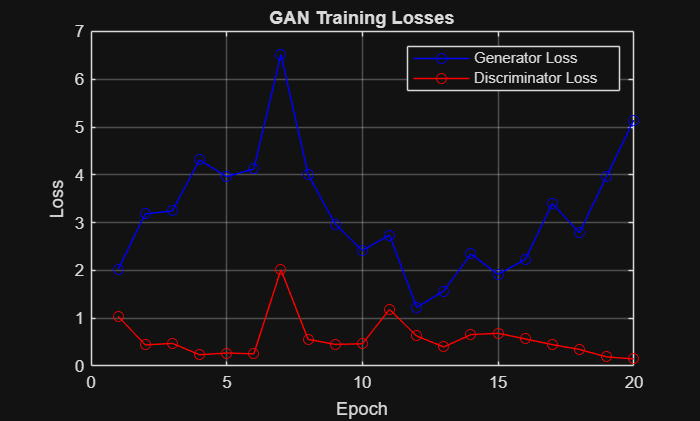


%% ── 8. Plot Training Losses ──────────────────────────────
figure;
plot(1:EPOCHS, G_losses, 'b-o', 1:EPOCHS, D_losses, 'r-o');
legend('Generator Loss','Discriminator Loss');
xlabel('Epoch'); ylabel('Loss');
title('GAN Training Losses');
grid on;

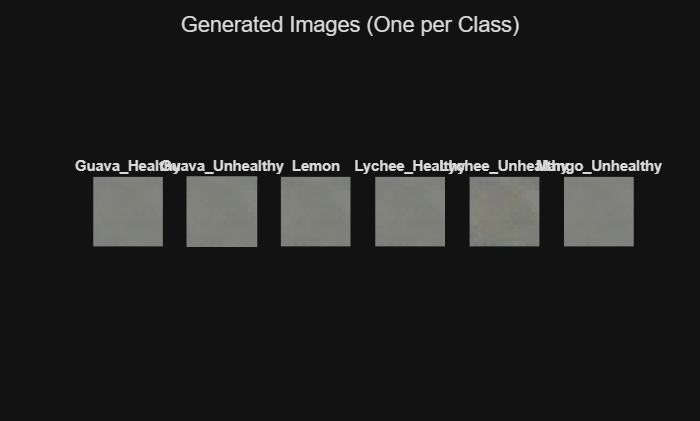


%% ── 9. Visualize Generated Images ────────────────────────
noiseVis  = randn(1, 1, nz, NUM_CLASSES, 'single');
labelVis  = makeConditionalMaps((1:NUM_CLASSES)', NUM_CLASSES, 1, 1);
genInputV = dlarray(cat(3, noiseVis, labelVis), 'SSCB');

fakeOut = extractdata(predict(dlnetG, genInputV));
fakeOut = (fakeOut + 1) / 2;
fakeOut = max(0, min(1, fakeOut));

figure;
for c = 1:NUM_CLASSES
    subplot(1, NUM_CLASSES, c);
    imshow(fakeOut(:,:,:,c));
    title(CLASS_NAMES{c}, 'Interpreter','none');
end
sgtitle('Generated Images (One per Class)');


%% ── 10. Save Models ──────────────────────────────────────
save(fullfile(MODELS_PATH, 'netG_conditional.mat'), 'dlnetG');
save(fullfile(MODELS_PATH, 'netD_conditional.mat'), 'dlnetD');
fprintf('Models saved.\n');

Models saved.



%% ── 11. Feature Extraction (Real Images) ─────────────────
reset(augimds);
X_real = [];
y_real = [];

fprintf('Extracting features from real images...\n');

Extracting features from real images...



while hasdata(augimds)
    [imgBatch, info] = read(augimds);
    if height(imgBatch) < 1, continue; end

    imgCell = table2cell(imgBatch(:,1));
    imgs    = single(cat(4, imgCell{:})) / 127.5 - 1;

    labels = double(info.Label);
    bsz    = numel(labels);

    labelMapsReal = makeConditionalMaps(labels, NUM_CLASSES, IMAGE_SIZE, IMAGE_SIZE);
    realIn        = dlarray(cat(3, imgs, labelMapsReal), 'SSCB');

    feats = forward(dlnetD, realIn, 'Outputs', 'lrelu4');
    feats = extractdata(feats);
    feats = reshape(feats, [], bsz)';

    X_real = [X_real; feats];     %#ok<AGROW>
    y_real = [y_real; labels(:)]; %#ok<AGROW>
end

fprintf('Feature shape: %d x %d\n', size(X_real,1), size(X_real,2));

Feature shape: 302 x 8192



%% Class distribution
fprintf('Class distribution:\n');

Class distribution:


for c = 1:NUM_CLASSES
    fprintf('  %s: %d\n', CLASS_NAMES{c}, sum(y_real == c));
end

  Guava_Healthy: 50
  Guava_Unhealthy: 50
  Lemon: 53
  Lychee_Healthy: 50
  Lychee_Unhealthy: 50
  Mango_Unhealthy: 49



%% ── 12. Generate Synthetic Samples ──────────────────────
TARGET_PER_CLASS = 100;
X_syn = [];
y_syn = [];

fprintf('Generating synthetic samples...\n');

Generating synthetic samples...



for cls = 1:NUM_CLASSES
    current = sum(y_real == cls);
    needed  = TARGET_PER_CLASS - current;

    if needed > 0
        noiseS  = randn(1, 1, nz, needed, 'single');
        labelsS = cls * ones(needed, 1);
        labelMS = makeConditionalMaps(labelsS, NUM_CLASSES, 1, 1);
        genInS  = dlarray(cat(3, noiseS, labelMS), 'SSCB');

        fakeImgs        = predict(dlnetG, genInS);
        fakeImgsResized = dlresize(fakeImgs, 'OutputSize', [64 64]);
        fakeDataR       = extractdata(fakeImgsResized);

        labelMD   = makeConditionalMaps(labelsS, NUM_CLASSES, 64, 64);
        fakeIn    = dlarray(cat(3, fakeDataR, labelMD), 'SSCB');

        fakeFeats = forward(dlnetD, fakeIn, 'Outputs', 'lrelu4');
        fakeFeats = extractdata(fakeFeats);
        fakeFeats = reshape(fakeFeats, [], needed)';

        X_syn = [X_syn; fakeFeats];  %#ok<AGROW>
        y_syn = [y_syn; labelsS];    %#ok<AGROW>
        fprintf('  %s → generated %d samples\n', CLASS_NAMES{cls}, needed);
    end
end

  Guava_Healthy → generated 50 samples
  Guava_Unhealthy → generated 50 samples
  Lemon → generated 47 samples
  Lychee_Healthy → generated 50 samples
  Lychee_Unhealthy → generated 50 samples
  Mango_Unhealthy → generated 51 samples



if ~isempty(X_syn)
    X_balanced = [X_real; X_syn];
    y_balanced = [y_real; y_syn];
else
    X_balanced = X_real;
    y_balanced = y_real;
end
fprintf('Balanced shape: %d x %d\n', size(X_balanced,1), size(X_balanced,2));

Balanced shape: 600 x 8192



%% ── 13. Train/Test Split ─────────────────────────────────
cv      = cvpartition(y_balanced, 'HoldOut', 0.2, 'Stratify', true);
X_train = X_balanced(training(cv), :);
y_train = y_balanced(training(cv));
X_test  = X_balanced(test(cv), :);
y_test  = y_balanced(test(cv));

%% ── 14. PILAE Classifier ─────────────────────────────────
if ~exist('X_train','var') || isempty(X_train)
    error('X_train is empty. Ensure Sections 11-13 ran successfully.');
end

Y_train_oh = full(ind2vec(y_train', NUM_CLASSES))';
W_pilae    = pinv(X_train) * Y_train_oh;

predictPILAE = @(X) vec2ind((X * W_pilae)')';

y_pred_train = predictPILAE(X_train);
y_pred_test  = predictPILAE(X_test);

train_acc = mean(y_pred_train == y_train);
test_acc  = mean(y_pred_test  == y_test);

fprintf('\nTrain Accuracy: %.4f\n', train_acc);


Train Accuracy: 1.0000


fprintf('Test  Accuracy: %.4f\n',  test_acc);

Test  Accuracy: 1.0000



fprintf('\nClassification Report (Balanced):\n');


Classification Report (Balanced):


fprintf('%-20s %8s %8s %8s\n','Class','Prec','Rec','F1');

Class                    Prec      Rec       F1


for c = 1:NUM_CLASSES
    tp   = sum(y_pred_test == c & y_test == c);
    fp   = sum(y_pred_test == c & y_test ~= c);
    fn   = sum(y_pred_test ~= c & y_test == c);
    prec = tp / max(tp+fp, 1);
    rec  = tp / max(tp+fn, 1);
    f1   = 2*prec*rec / max(prec+rec, 1e-8);
    fprintf('%-20s %8.4f %8.4f %8.4f\n', CLASS_NAMES{c}, prec, rec, f1);
end

Guava_Healthy          1.0000   1.0000   1.0000
Guava_Unhealthy        1.0000   1.0000   1.0000
Lemon                  1.0000   1.0000   1.0000
Lychee_Healthy         1.0000   1.0000   1.0000
Lychee_Unhealthy       1.0000   1.0000   1.0000
Mango_Unhealthy        1.0000   1.0000   1.0000


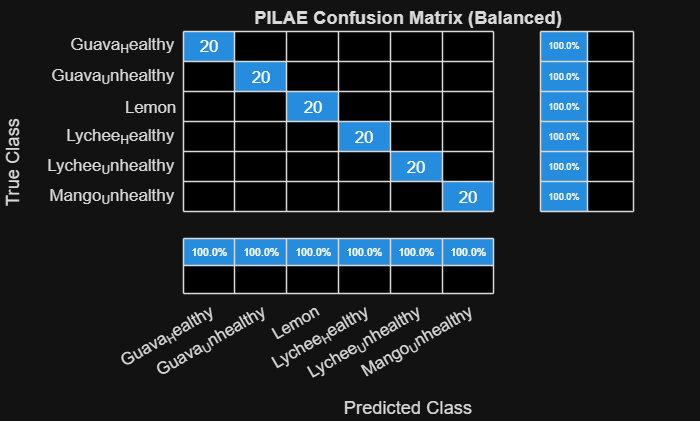


figure;
confusionchart( ...
    categorical(y_test,      1:NUM_CLASSES, CLASS_NAMES), ...
    categorical(y_pred_test, 1:NUM_CLASSES, CLASS_NAMES), ...
    'RowSummary','row-normalized', ...
    'ColumnSummary','column-normalized');
title('PILAE Confusion Matrix (Balanced)');


%% ── 15. Real-Only Baseline ───────────────────────────────
if ~exist('X_real','var') || isempty(X_real)
    error('X_real is empty. Ensure Section 11 ran successfully.');
end

cv_r      = cvpartition(y_real, 'HoldOut', 0.2, 'Stratify', true);
X_train_r = X_real(training(cv_r), :);
y_train_r = y_real(training(cv_r));
X_test_r  = X_real(test(cv_r), :);
y_test_r  = y_real(test(cv_r));

Y_train_r_oh = full(ind2vec(y_train_r', NUM_CLASSES))';
W_real       = pinv(X_train_r) * Y_train_r_oh;
y_pred_r     = vec2ind((X_test_r * W_real)')';
real_acc     = mean(y_pred_r == y_test_r);

fprintf('\nReal-only Accuracy: %.4f\n', real_acc);


Real-only Accuracy: 1.0000


fprintf('Classification Report (Real-only):\n');

Classification Report (Real-only):


fprintf('%-20s %8s %8s %8s\n','Class','Prec','Rec','F1');

Class                    Prec      Rec       F1


for c = 1:NUM_CLASSES
    tp   = sum(y_pred_r == c & y_test_r == c);
    fp   = sum(y_pred_r == c & y_test_r ~= c);
    fn   = sum(y_pred_r ~= c & y_test_r == c);
    prec = tp / max(tp+fp, 1);
    rec  = tp / max(tp+fn, 1);
    f1   = 2*prec*rec / max(prec+rec, 1e-8);
    fprintf('%-20s %8.4f %8.4f %8.4f\n', CLASS_NAMES{c}, prec, rec, f1);
end

Guava_Healthy          1.0000   1.0000   1.0000
Guava_Unhealthy        1.0000   1.0000   1.0000
Lemon                  1.0000   1.0000   1.0000
Lychee_Healthy         1.0000   1.0000   1.0000
Lychee_Unhealthy       1.0000   1.0000   1.0000
Mango_Unhealthy        1.0000   1.0000   1.0000


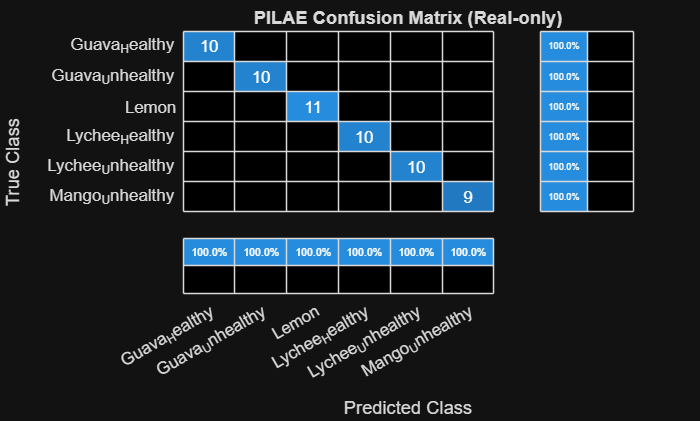


figure;
confusionchart( ...
    categorical(y_test_r, 1:NUM_CLASSES, CLASS_NAMES), ...
    categorical(y_pred_r, 1:NUM_CLASSES, CLASS_NAMES), ...
    'RowSummary','row-normalized', ...
    'ColumnSummary','column-normalized');
title('PILAE Confusion Matrix (Real-only)');